# Zebrafish Detection Demonstration

## Maxwell Greene

%Parameters
backDif    = 25; %Background difference
noiseSize  = 5;  %Size of particles to keep
medFiltRad = 15; %Radius to evaluate median filter
skelSize   = 20; %Size to evaluate skeleton

## Import Image

image = imread('Data/example2.jpg');
background = imread('Data/backGround.jpg');

## Show Background & Image

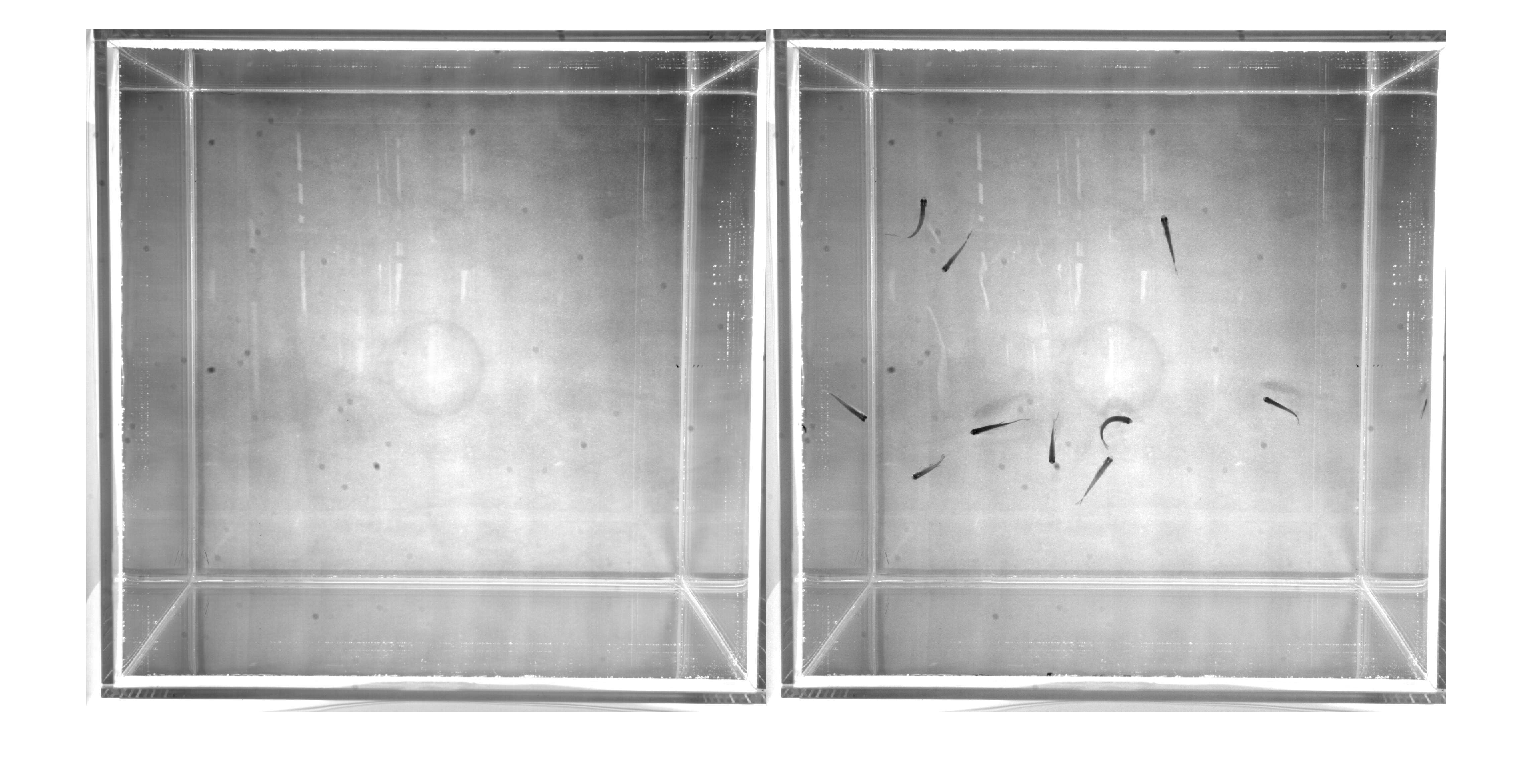

imshowpair(background,image,'montage');

## Subtract Background & Fill holes

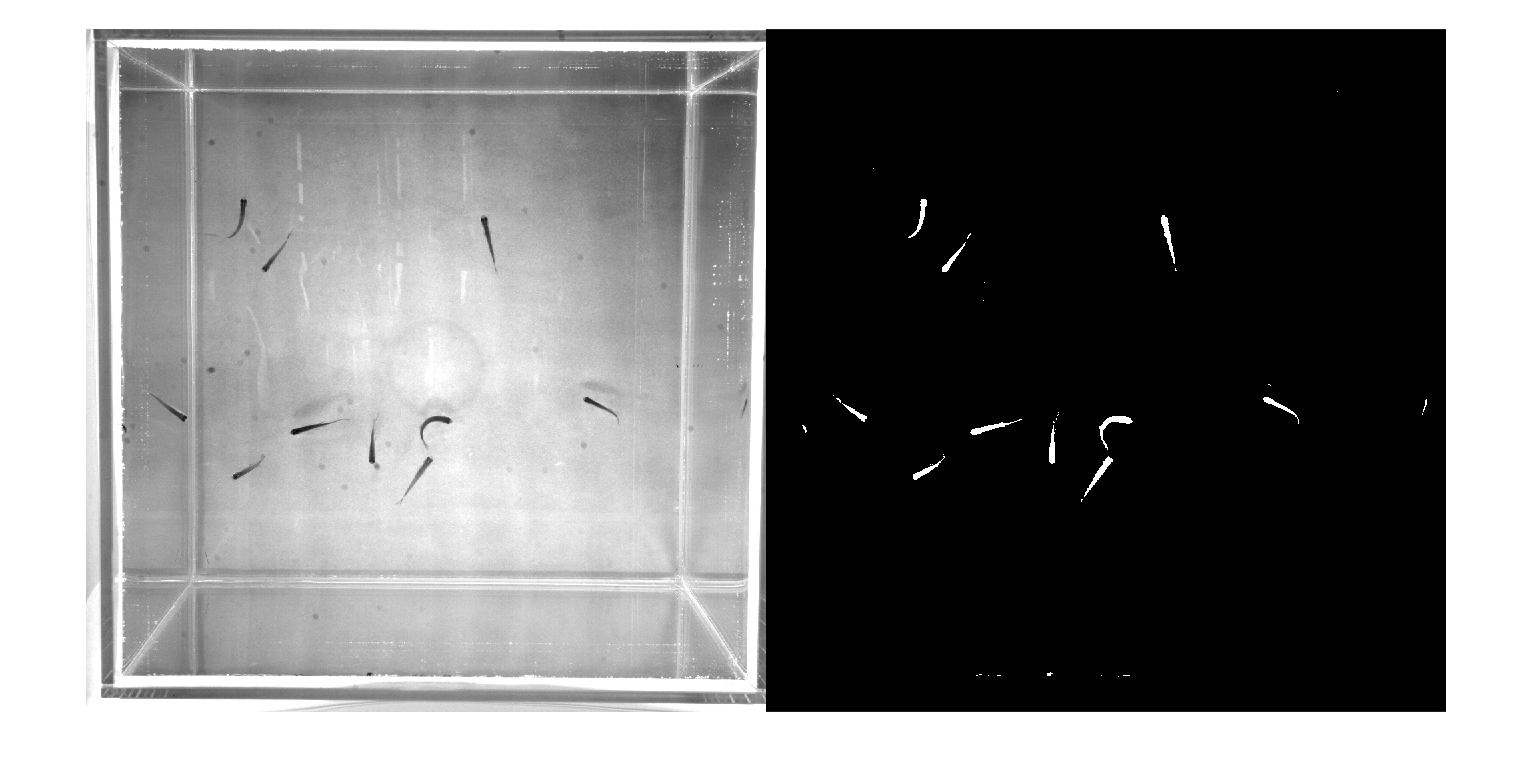

image1 = background(:,:) - image(:,:) > backDif;
image2 = imfill(image1,'holes');
imshowpair(image,image2,'montage');

## Show a histogram of subtracted image contents

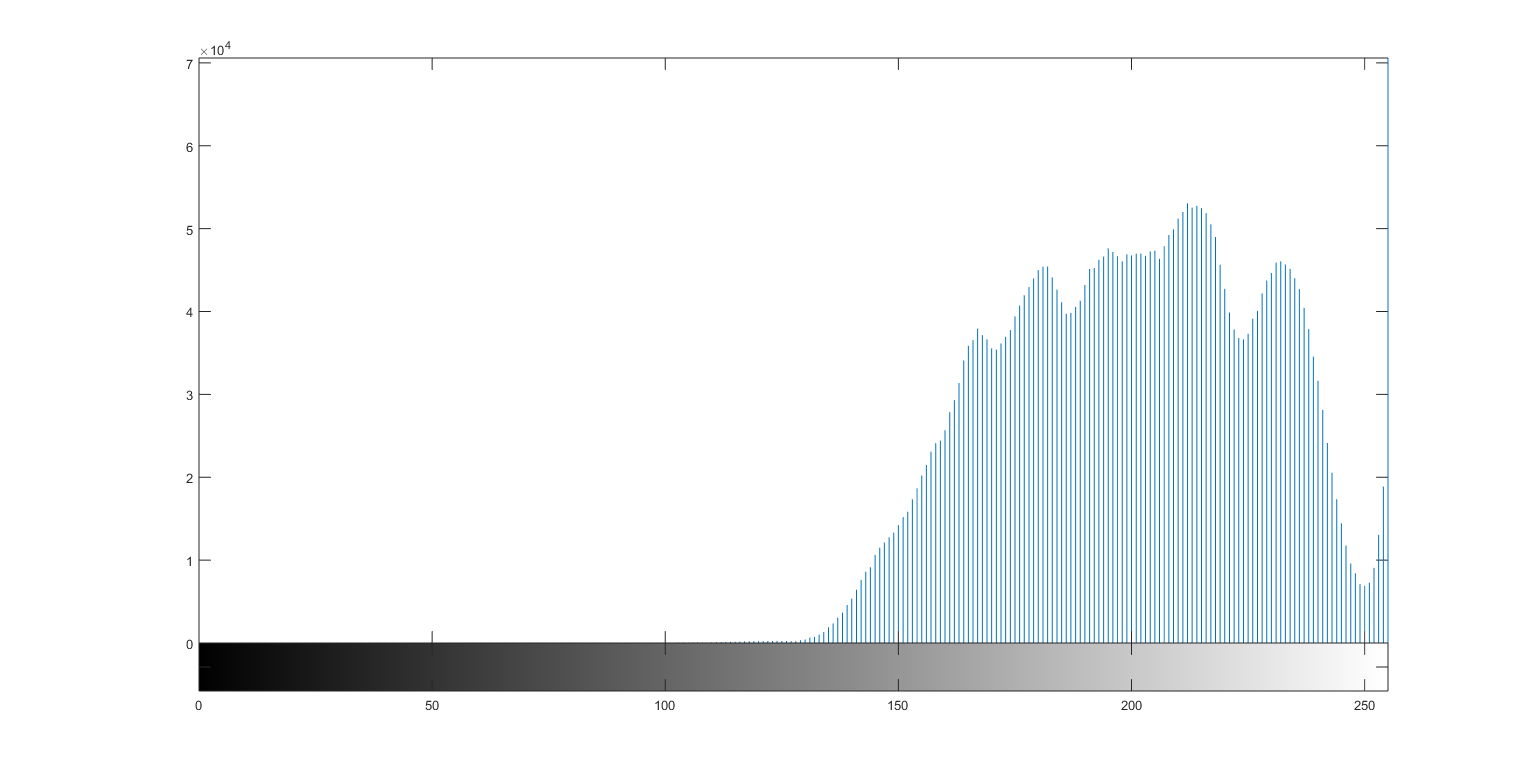

imhist(image);

## Remove Small Objects

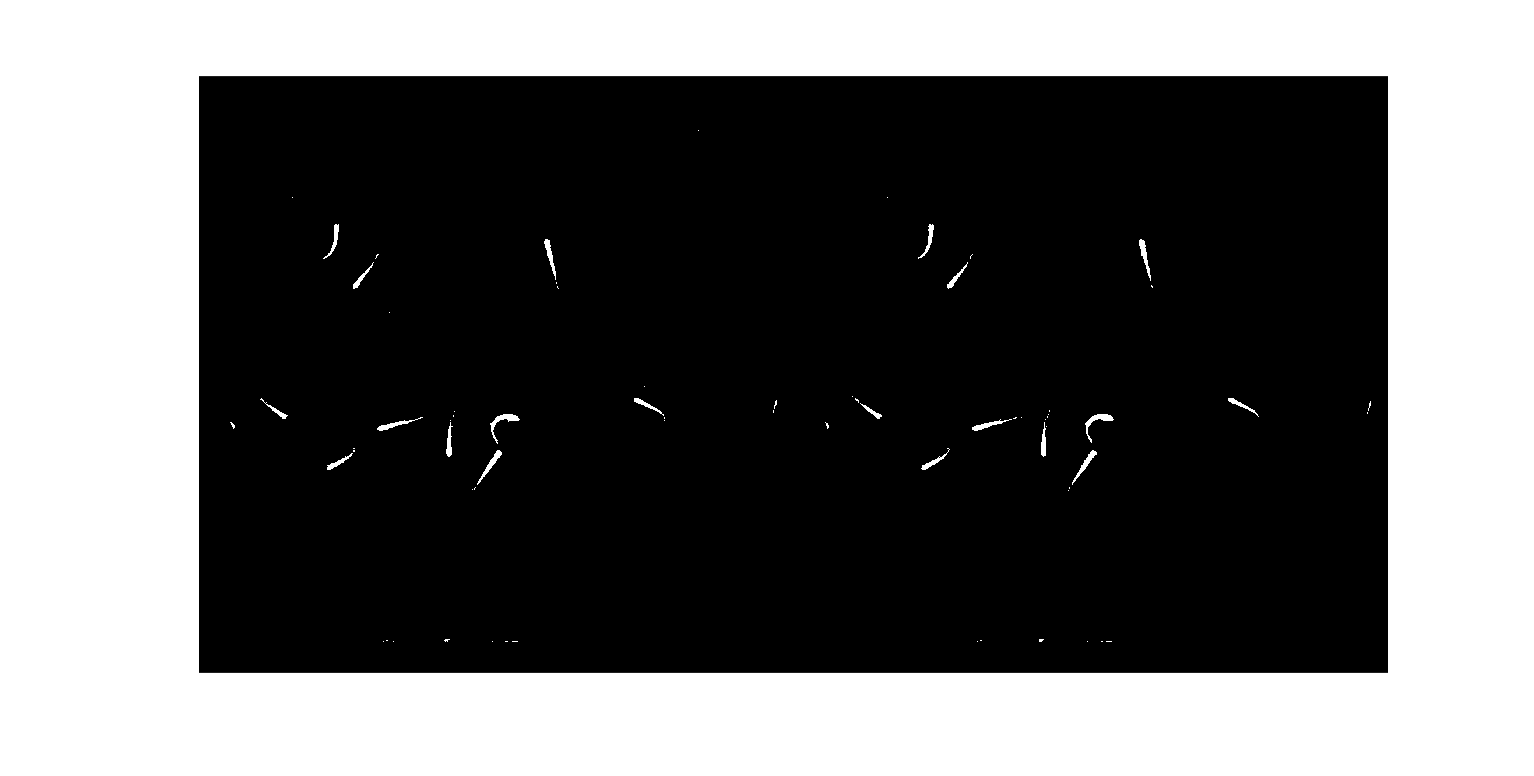

image3 = bwareaopen(image2,noiseSize);
imshowpair(image2,image3,'montage');

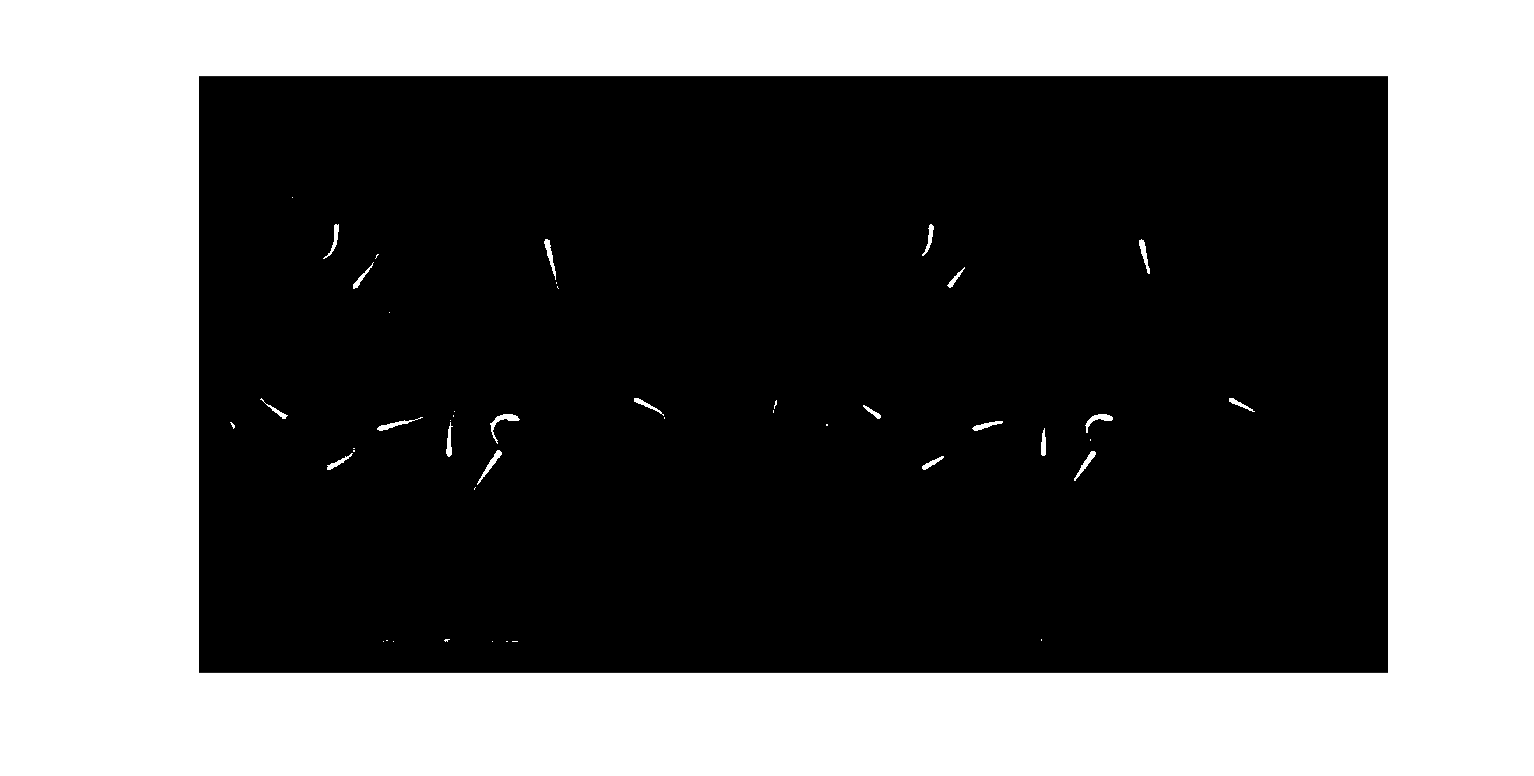

image4 = medfilt2(image3,[medFiltRad,medFiltRad]);
imshowpair(image3,image4,'montage');

## Mark Out Skeleton

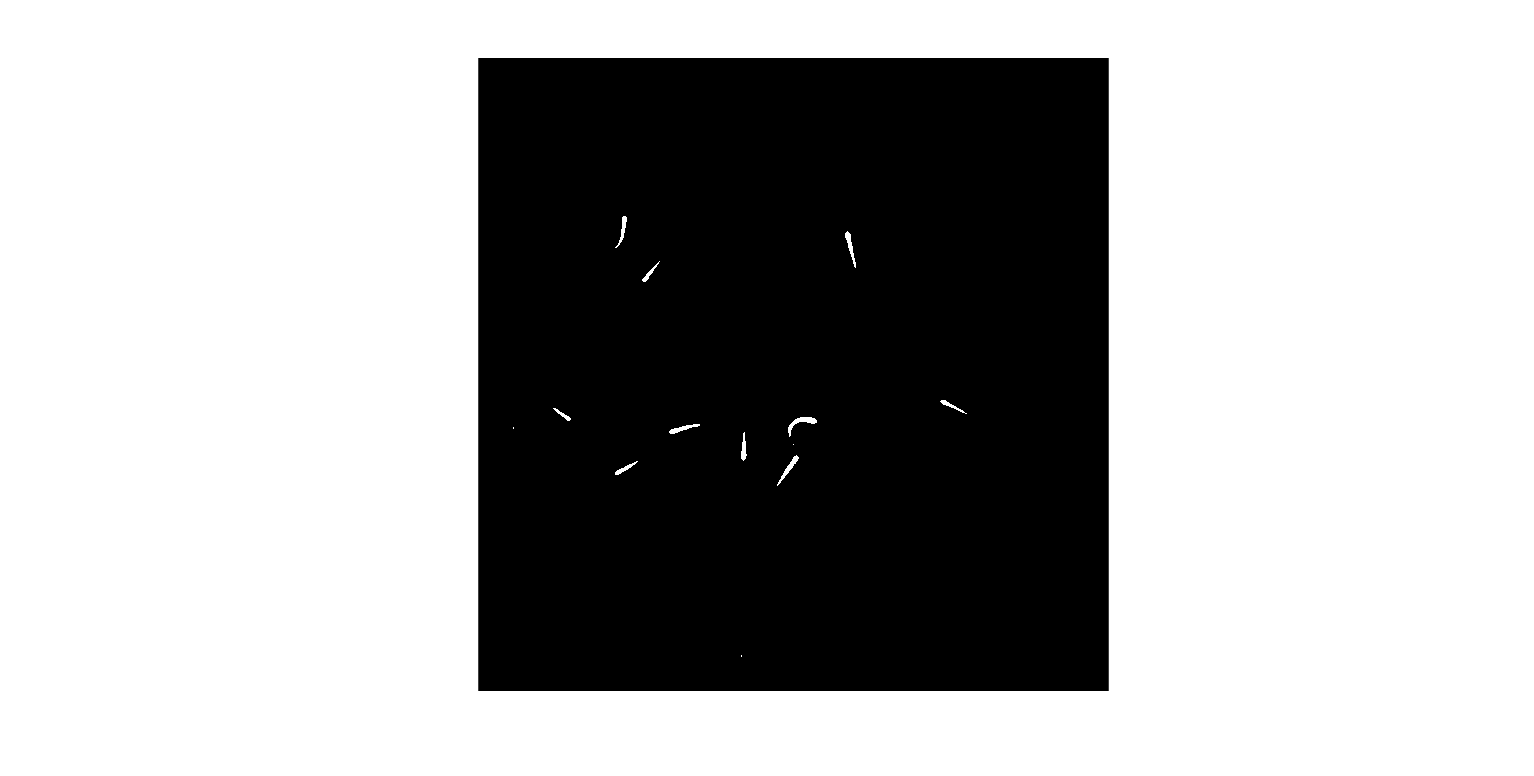

[ske, r] = skeleton(image4);
imshow(r);

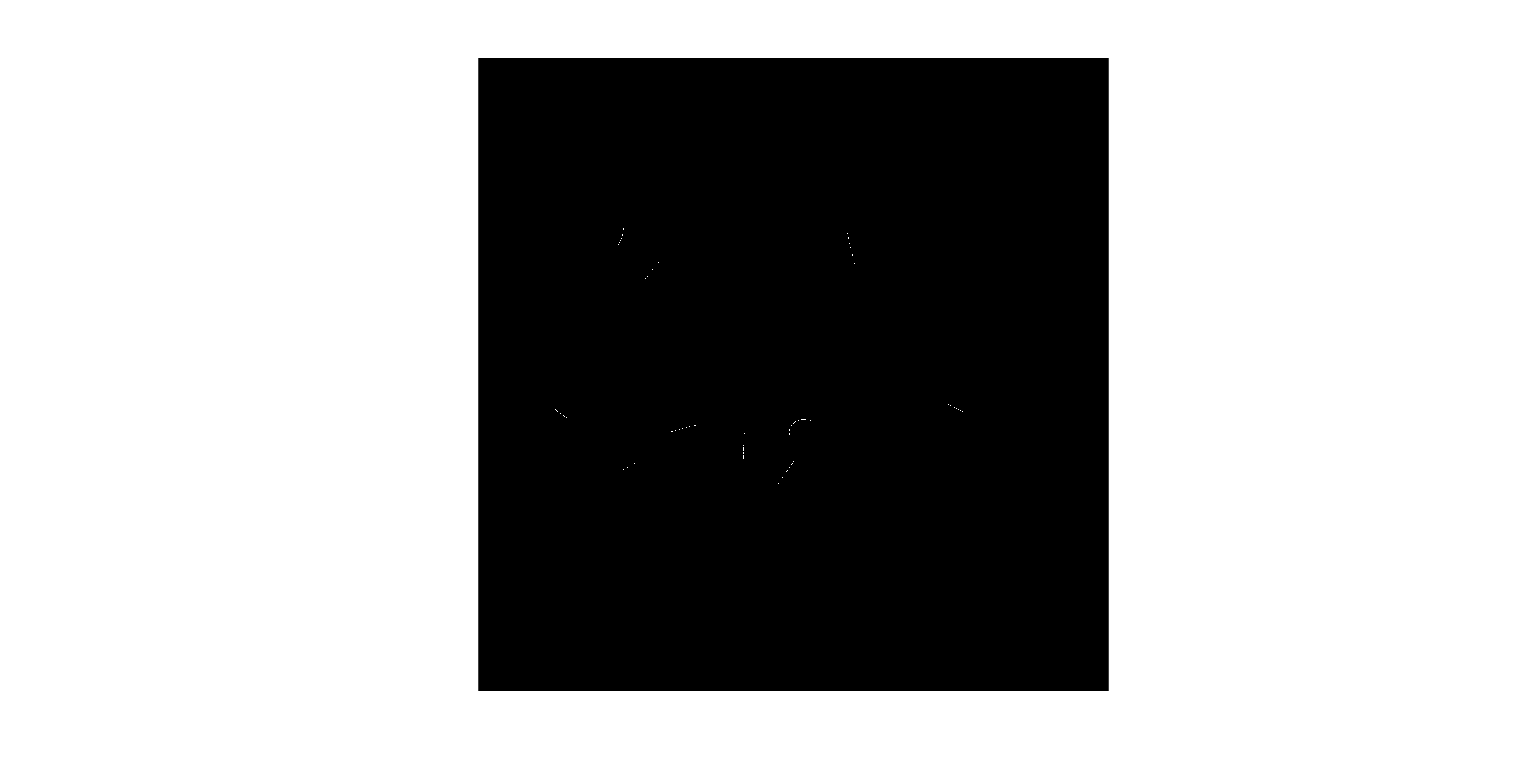

mainske = bwmorph(ske > skelSize, 'thin', inf);
imshow(mainske);

[d, ep, jp] = skeanalysis(mainske);
figure();imshow(image);hold on;

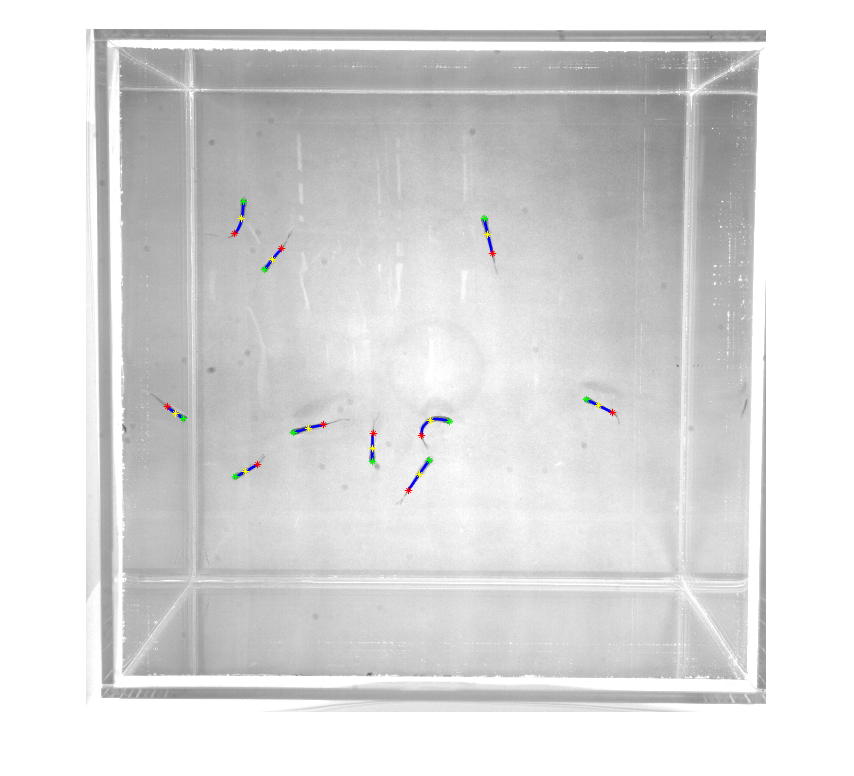

skemark(mainske, ske, ep, jp, r);